# COVID19 Mask Detection

## Labeling Automation Workflow

Label image with Automation algorithm

Prototype with sample image

imds = imageDatastore("SampleMaskData\")

imds =   ImageDatastore - 속성 있음:

                       Files: {
                              ' ...\COVID_Project\mask\FEX_Submission\SampleMaskData\a01.jpg';
                              ' ...\COVID_Project\mask\FEX_Submission\SampleMaskData\a02.jpg';
                              ' ...\COVID_Project\mask\FEX_Submission\SampleMaskData\a03.jpg'
                               ... and 5 more
                              }
                     Folders: {
                              ' ...\Demos\Deep Learning\COVID_Project\mask\FEX_Submission\SampleMaskData'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


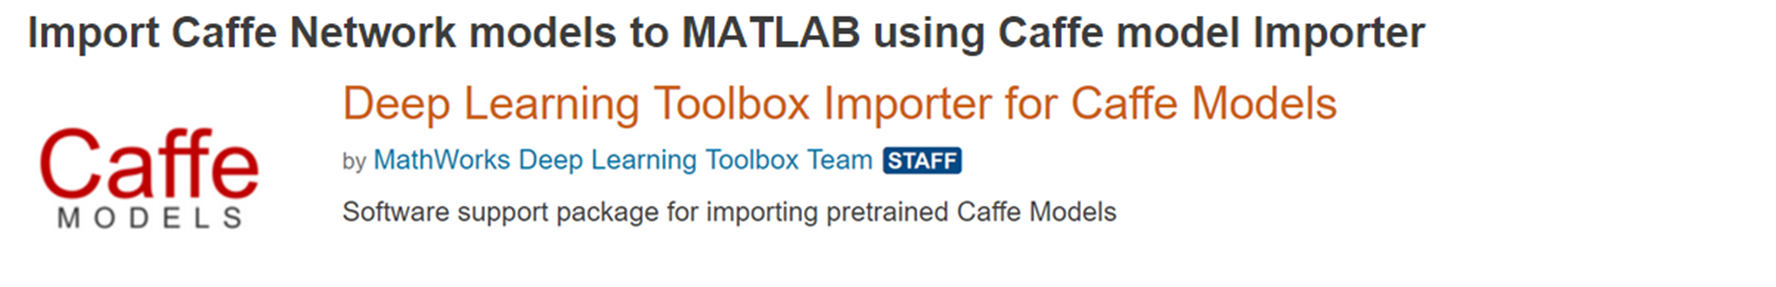

Download Caffe model and protofile for face detection

modelFolder = 'models';
if ~isfolder('models')
    mkdir(modelFolder)
end
modelFaceYolo = 'net_face_yolo';
if ~isfile(fullfile(modelFolder,[modelFaceYolo,'.mat']))
    fprintf(1,'Downloading Caffe model for face detection...');
    netFaceYoloModelFilename = websave(fullfile(modelFolder,[modelFaceYolo,'.caffemodel']), ...
        'http://www.abars.biz/keras/face.caffemodel');
    netFaceYoloProtoFilename = websave(fullfile(modelFolder,[modelFaceYolo,'_deploy.prototxt']), ...
        'http://www.abars.biz/keras/face.prototxt');
    fprintf(1,'[DONE]\n')
end

Prepare face detection network in MATLAB format

doImportandSave = false;
if doImportandSave
    faceYoloNet = importCaffeNetwork('models\net_face_yolo_deploy.prototxt', ...
        'models\net_face_yolo.caffemodel','OutputLayerType','regression');
    save models\net_face_yolo.mat faceYoloNet
end

Read sample image

img = read(imds);
ori_sz = size(img, [1 2]);
re_sz = [448 448];
imgr = imresize(img, re_sz);
scale = ori_sz./re_sz;

Rescale the bouding box with respect to the original image

bbox = predictFace(imgr, 'models\net_face_yolo.mat');

Assume that the lower half part could be the mask.

bbox(:,4) = bbox(:,4)./2+20;
bbox(:,2) = bbox(:,2)+bbox(:,4)-20;
bbox(:,3) = bbox(:,3)+20;
bbox = bboxresize(round(bbox),scale);

Draw the returned bounding box around the detected face.

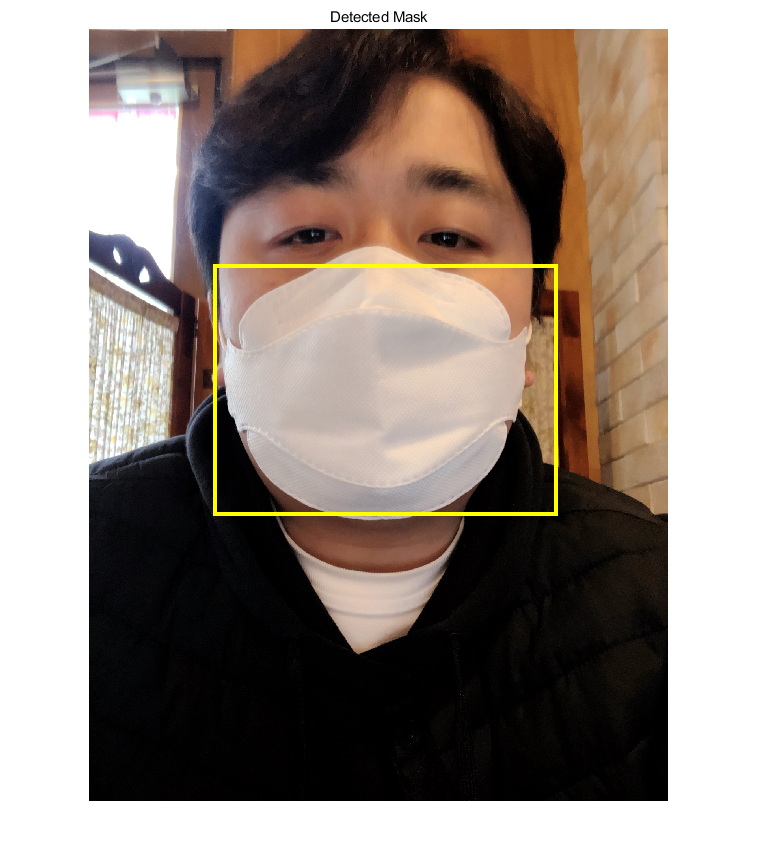

img = insertShape(img, 'Rectangle', bbox, 'LineWidth', 15);
figure; imshow(img); title('Detected Mask');

#### Let's automate this

imageLabeler

*Copyright 2020 The MathWorks, Inc.*